# t_initAnatomyFromFreesurfer

Illustrates how to initialize the volume anatomy and class file from a freesurfer directory. Uses the sample freesurfer data set [ernie](ernie)

**Dependencies**: 

- Freesurfer 

- Remote Data Toolbox

**Summary**

- Download freesurfer ernie directory

- Create t1 anatomy and t1 class files from freesurfer

- Visualize the two images

Tested 07/20/2016 - MATLAB r2015a, Mac OS 10.11.6 

Tested 10/03/2018 - MATLAB r2017b, Mac OS 10.13.6

*See also*: t_initVistaSession.m

Winawer lab (NYU)

## Download ernie freesurfer directory

% Check whether freesurfer paths exist
fssubjectsdir = getenv('SUBJECTS_DIR');
if isempty(fssubjectsdir)
    error('Freesurfer paths not found. Cannot proceed.')
end

% Get ernie freesurfer directory and install it in freesurfer subjects dir
%   If we find the directory, do not bother unzipping again
forceOverwrite = false; 

% Do it
dataDir = mrtInstallSampleData('anatomy/freesurfer', 'ernie', ...
    fssubjectsdir, forceOverwrite);

Data directory /Volumes/server/Freesurfer_subjects/ernie already exists. Skipping unzip.



fprintf('Freesurfer directory for ernie installed here:\n %s\n', dataDir)

Freesurfer directory for ernie installed here:
 /Volumes/server/Freesurfer_subjects/ernie


## Create t1 anatomy and t1 class files from freesurfer

Store current directory

curdir = pwd(); 

%       This is the path where we will set up the vista session
erniePathTemp      = fullfile(vistaRootPath, 'local', 'scratch', 'erniePRF');
mkdir(erniePathTemp);

% Navigate 
cd(erniePathTemp)

% Create t1 anatomy and class file
mkdir 3DAnatomy;
outfile = fullfile('3DAnatomy', 't1_class.nii.gz');
fillWithCSF = true;
alignTo = fullfile(dataDir, 'mri', 'orig.mgz');
fs_ribbon2itk('ernie', outfile, fillWithCSF, alignTo);

mri_convert.bin -rt nearest /Volumes/server/Freesurfer_subjects/ernie/mri/orig.mgz 3DAnatomy/t1.nii.gz 
$Id: mri_convert.c,v 1.226 2016/02/26 16:15:24 mreuter Exp $
reading from /Volumes/server/Freesurfer_subjects/ernie/mri/orig.mgz...
TR=0.00, TE=0.00, TI=0.00, flip angle=0.00
i_ras = (-1, 0, 0)
j_ras = (0, 0, -1)
k_ras = (0, 1, 0)
writing to 3DAnatomy/t1.nii.gz...
mri_convert.bin --reslice_like 3DAnatomy/t1.nii.gz -rt nearest /Volumes/server/Freesurfer_subjects/ernie/mri/ribbon.mgz 3DAnatomy/t1_class.nii.gz 
$Id: mri_convert.c,v 1.226 2016/02/26 16:15:24 mreuter Exp $
reading from /Volumes/server/Freesurfer_subjects/ernie/mri/ribbon.mgz...
TR=0.00, TE=0.00, TI=0.00, flip angle=0.00
i_ras = (-1, 0, 0)
j_ras = (0, 0, -1)
k_ras = (0, 1, 0)
reading template info from volume 3DAnatomy/t1.nii.gz...
writing to 3DAnatomy/t1_class.nii.gz...


****************
Converting voxels....

Number of L Gray voxels 	= 268982
Number of L White voxels 	= 299585
Number of R White voxels 	= 302175
Number o

 
% Check that you created a t1 class file (ribbon) and t1 anatomy
ls 3DAnatomy  

t1.nii.gz	t1_class.nii.gz




% The command window should show:
%       t1.nii.gz	t1_class.nii.gz

## Visualize

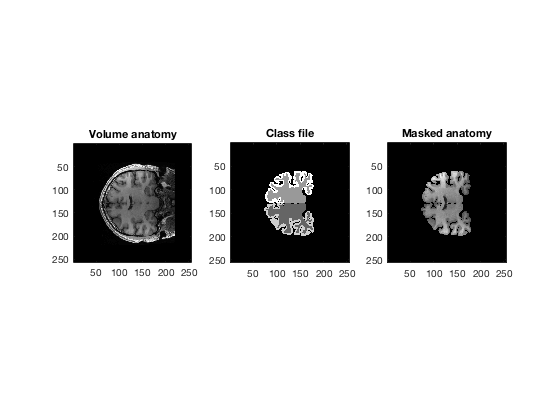

% Show the volume anatomy, segmentation, and anatomy masked by segmentation
ni = niftiRead(fullfile('3DAnatomy', 't1.nii.gz'));
t1 = niftiGet(ni, 'data');
ni = niftiRead(fullfile('3DAnatomy', 't1_class.nii.gz'));
cl = niftiGet(ni, 'data');

fH = figure('Color','w');

% Choose one slice to visualize from the middle of head
sliceNum = size(t1,3)/2;

% Volume anatomy, 
subplot(1,3,1)
imagesc(t1(:,:,sliceNum), [0 255]); colormap gray; axis image
title('Volume anatomy')

subplot(1,3,2)
imagesc(cl(:,:,sliceNum), [1 6]);   axis image
title('Class file')

subplot(1,3,3)
mask = cl(:,:,sliceNum) > 1;
imagesc(t1(:,:,sliceNum) .* uint8(mask));   axis image
title('Masked anatomy')

## Clean up

cd(curdir)